**Sistemas de Ecuaciones Lineales**

clear
% Sistema:
A = [ 4 -1 2
      2 6 3
     -1 2 5]

A =      4    -1     2
     2     6     3
    -1     2     5


b = [8 -12 10]'

b =      8
   -12
    10


**1) Convergencia:**

**1.1 Diagonal Dominancia:**

op = 1; % A es D.E.D
[m,n] = size(A); % m fil, n col
for i=1:m
    if abs(A(i,i)) <= sum(abs(A(i,:))) - abs(A(i,i))
        op = 0; % A es D.E.D
    end
end

if op == 1
    disp('A es D.E.D, por tanto el método iterativo CONVERGE')
else
    disp('A no es D.E.D, por tanto no puedo afirmar nada')
end

A es D.E.D, por tanto el método iterativo CONVERGE


**1.2 Radio Espectral:**

% El criterio de radio espectral se aplica a la
% la matriz de iteraciones del método iterativo

% Método de Jacobi:
D = diag(diag(A));
L = -tril(A,-1);
U = -triu(A,1);
Tj = inv(D)*(L+U);
rhoTj = max(abs(eig(Tj)))

rhoTj = 0.4632

if rhoTj < 1
    disp('El método de Jacobi CONVERGE');
else
    disp('El método de Jacobi NO CONVERGE');
end

El método de Jacobi CONVERGE


% Método de Gauss-Seidel:
D = diag(diag(A));
L = -tril(A,-1);
U = -triu(A,1);
Tgs = inv(D-L)*U;
rhoTgs = max(abs(eig(Tgs)))

rhoTgs = 0.1581

if rhoTgs < 1
    disp('El método de Gauss-Seidel CONVERGE');
else
    disp('El método de Gauss-Seidel NO CONVERGE');
end

El método de Gauss-Seidel CONVERGE


**2)   MÉTODO DE JACOBI:**

% function z = jacobi(A,b,x0,Tol)

A = [ 4 -1 2
      2 6 3
     -1 2 5];
b = [8 -12 10]';
x0 = [0 0 0]';
Tol = 0.0001;

dr = 1;
D = diag(diag(A));
L = -tril(A,-1);
U = -triu(A,1);
Tj = inv(D)*(L+U);
cj = inv(D)*b;
i = 0;
z = [i x0' dr];
while(dr>Tol)
    % Método Numérico
    x1 = Tj*x0 + cj;
    % Calcular el error
    dr = norm(x1-x0,'inf')/norm(x1,'inf');
    i = i + 1;
    z = [z; i x1' dr];
    % Actualizar las variables previas
    x0 = x1;
end
disp(z);

         0         0         0         0    1.0000
    1.0000    2.0000   -2.0000    2.0000    1.0000
    2.0000    0.5000   -3.6667    3.2000    0.4545
    3.0000   -0.5167   -3.7667    3.5667    0.2699
    4.0000   -0.7250   -3.6111    3.4033    0.0577
    5.0000   -0.6044   -3.4600    3.2994    0.0437
    6.0000   -0.5147   -3.4482    3.2631    0.0260
    7.0000   -0.4936   -3.4600    3.2764    0.0061
    8.0000   -0.5032   -3.4736    3.2853    0.0039
    9.0000   -0.5110   -3.4749    3.2888    0.0023
   10.0000   -0.5131   -3.4741    3.2878    0.0006
   11.0000   -0.5124   -3.4728    3.2870    0.0004
   12.0000   -0.5117   -3.4727    3.2867    0.0002
   13.0000   -0.5115   -3.4728    3.2867    0.0001



clear;

A = [ 4 -1 2
      2 6 3
     -1 2 5];
b = [8 -12 10]';
x0 = [0 0 0]';
Tol = 0.0001;

[tabla_j,xr] = jacobi(A,b,x0,Tol)

tabla_j =          0         0         0         0    1.0000
    1.0000    2.0000   -2.0000    2.0000    1.0000
    2.0000    0.5000   -3.6667    3.2000    0.4545
    3.0000   -0.5167   -3.7667    3.5667    0.2699
    4.0000   -0.7250   -3.6111    3.4033    0.0577
    5.0000   -0.6044   -3.4600    3.2994    0.0437
    6.0000   -0.5147   -3.4482    3.2631    0.0260
    7.0000   -0.4936   -3.4600    3.2764    0.0061
    8.0000   -0.5032   -3.4736    3.2853    0.0039
    9.0000   -0.5110   -3.4749    3.2888    0.0023


xr =    -0.5115
   -3.4728
    3.2867


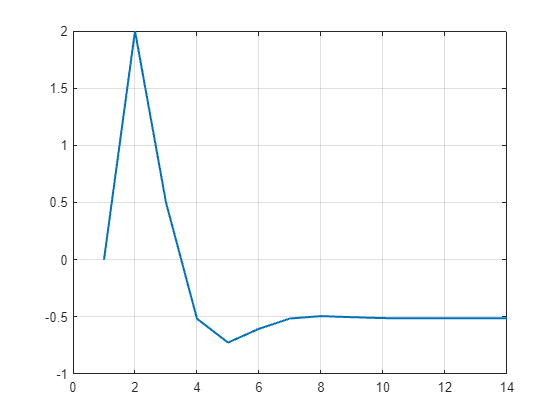

figure(1); clf;
plot(tabla_j(:,2),'LineWidth',1.5); grid on;

**2)   MÉTODO DE GAUSS-SEIDEL:**

A = [ 4 -1 2
      2 6 3
     -1 2 5];
b = [8 -12 10]';
x0 = [0 0 0]';
Tol = 0.0001;

[tabla_gs,xr_gs] = gauss_seidel(A,b,x0,Tol)

tabla_gs =          0         0         0         0    1.0000
    1.0000    2.0000   -2.6667    3.4667    1.0000
    2.0000   -0.4000   -3.6000    3.3600    0.6667
    3.0000   -0.5800   -3.4867    3.2787    0.0516
    4.0000   -0.5110   -3.4690    3.2854    0.0199
    5.0000   -0.5099   -3.4727    3.2871    0.0011
    6.0000   -0.5117   -3.4730    3.2868    0.0005
    7.0000   -0.5117   -3.4729    3.2868    0.0000


xr_gs =    -0.5117
   -3.4729
    3.2868


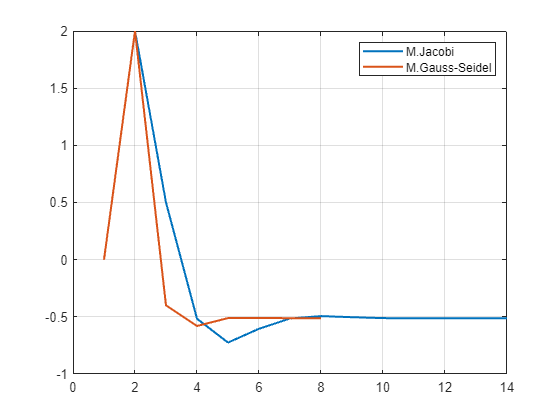

figure(1); clf;
plot(tabla_j(:,2),'LineWidth',1.5); grid on; hold on;
plot(tabla_gs(:,2),'LineWidth',1.5);
legend('M.Jacobi','M.Gauss-Seidel')

function [z,x1] = jacobi(A,b,x0,Tol)
    dr = 1;
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);
    Tj = inv(D)*(L+U);
    cj = inv(D)*b;
    i = 0;
    z = [i x0' dr];
    while(dr>Tol)
        % Método Numérico
        x1 = Tj*x0 + cj;
        % Calcular el error
        dr = norm(x1-x0,'inf')/norm(x1,'inf');
        i = i + 1;
        z = [z; i x1' dr];
        % Actualizar las variables previas
        x0 = x1;
    end
end

function [z,x1] = gauss_seidel(A,b,x0,Tol)
    dr = 1;
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);
    Tgs = inv(D-L)*(U);
    cgs = inv(D-L)*b;
    i = 0;
    z = [i x0' dr];
    while(dr>Tol)
        % Método Numérico
        x1 = Tgs*x0 + cgs;
        % Calcular el error
        dr = norm(x1-x0,'inf')/norm(x1,'inf');
        i = i + 1;
        z = [z; i x1' dr];
        % Actualizar las variables previas
        x0 = x1;
    end
end